# II. Quantum EigenModes of a Potential

Schrodinger equation: 


$$i\hbar\frac{\partial\Psi}{\partial t} = -\frac{\hbar^2}{2m}\frac{\partial^2\Psi}{\partial z^2} + V(z)\Psi$$


When we consider the time dependent wavefunction to be representable as $\Psi(z,t) = \psi(z)e^{-iEt/\hbar}$ then we can write the time independent schrodinger equation as 


$$E_j \psi_j(z) = -\frac{\hbar^2}{2m}\frac{d^2\psi_j}{dz^2} + V(z)\psi_j\quad,\quad j = 0,1,2,3,\dots$$


We'll represent the solutions to this equation for the quantum harmonic oscillator as the hermite guassian solution set. 

$\psi_j(z) = \mathcal{N}_j H_j(z\,/\,z_0)e^{-z^2/2z_0^2}$ where the oscillator length is $z_0 = \sqrt{\frac{\hbar}{m\omega}}$ and $z_j = z_{0}\sqrt{2j + 1}$ 

In order to approach the problem numerically, we need continuous space into a set of discrete points given by $z_\mu = \frac{z_{max}}{2} + (\mu -1)\Delta z\quad,\quad \mu = 1,2,\dots,N$ where $\Delta z = z_{max}/(N-1)$

The second approximation is performed on the second derivative $\frac{d^2\psi}{dz^2}\rightarrow \frac{(\psi_{\mu+1} - 2\psi_\mu +\psi_{\mu-1})}{\Delta z^2}$ such that we can write the hamiltonian as 


$$H_{\mu,\nu} = \bigl[V_\mu + \frac{\hbar^2}{m\Delta z^2}\bigl]\delta_{\mu,\nu} - \frac{\hbar^2}{2m\Delta z^2}[\delta_{\mu,\nu +1} + \delta_{\mu,\nu - 1}]$$


$\Delta z << z_0$ and $z_{max} >> z_0$

## C. Quantum harmonic oscillator

b.) 

clear; close all;
z0 = 1e-6;   % beam width of 1um

I will choose $\Delta z = z_0/10$ and $z_{max} = 10z_0$

deltaZ = z0/10;     % step size
zmax = 10*z0;        % maximum grid extent
N = zmax/deltaZ + 1        % number of points in grid

N = 101

This means that there will be 101 eigenvalue/eigenvector pairs for `eigs` to compute.

mu = 1:N;
z_mu = -zmax/2 + (mu -1)*deltaZ;
h = zeros(N,N);
% create the hamiltonian matrix h
for i = 1:N
    for j = 1:N
        if i == j
            h(i,j) = (1/2)*(z_mu(i)/z0)^2 + (z0/deltaZ)^2;
        elseif i ==(j+ 1) || i == (j - 1)
            h(i,j) = -(1/2)*(z0/deltaZ)^2;
        end
    end
end

I will label the eigenvectors as `V = PSI` and the eigenvalues as `D = E`

% find eigenvectors and eigenvalues
[PSI,E] = eigs(h,N,'smallestabs')

PSI =     0.0000   -0.0000   -0.0000    0.0001    0.0002   -0.0006   -0.0015    0.0031    0.0060   -0.0104   -0.0163    0.0230    0.0301   -0.0371   -0.0436    0.0496    0.0551   -0.0603   -0.0652    0.0698    0.0742   -0.0784   -0.0824    0.0862    0.0899   -0.0935   -0.0969    0.1002    0.1034   -0.1064   -0.1093    0.1121    0.1147   -0.1172   -0.1196    0.1218    0.1239   -0.1259   -0.1278    0.1295    0.1311   -0.1326   -0.1339    0.1351    0.1362   -0.1371   -0.1379    0.1385    0.1391   -0.1395
    0.0000   -0.0000   -0.0000    0.0002    0.0005   -0.0013   -0.0031    0.0066    0.0126   -0.0215   -0.0332    0.0465    0.0602   -0.0731   -0.0848    0.0951    0.1042   -0.1121   -0.1190    0.1250    0.1302   -0.1347   -0.1383    0.1413    0.1436   -0.1453   -0.1462    0.1466    0.1463   -0.1455   -0.1440    0.1420    0.1394   -0.1362   -0.1326    0.1284    0.1238   -0.1187   -0.1131    0.1072    0.1008   -0.0942   -0.0871    0.0798    0.0722   -0.0644   -0.0564    0.0482    0.0398   

E =     0.4997         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    1.4984         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0     

Potential pitfalls of this chosen grid: 

- The criterion that $z_{max} = 10z_0$ make be too finely meshed.

c.) In general, an order of magnitude difference between $\Delta z$ and $z_0$ is good.

deltaZ/z0

ans = 0.1000

We know analytically that $E_j = \hbar\omega(j + 1/2)$ are the eigenvalues of the quantum harmonic oscillator. If we run a check to see the error between the 10 lowest eigenvalues calculated numerically versus the analytic values we get the following:

Ej = eigs(h,10,'smallestabs')

Ej =     0.4997
    1.4984
    2.4959
    3.4922
    4.4872
    5.4809
    6.4736
    7.4660
    8.4605
    9.4637


E_analytic = zeros(10,1);
for i=1:10
    E_analytic(i) = (i-1) + 1/2;
end

E_analytic =     0.5000
    1.5000
    2.5000
    3.5000
    4.5000
    5.5000
    6.5000
    7.5000
    8.5000
    9.5000


Tol = E_analytic - Ej % shows a small error between the numeric and the analytic values.

Tol =     0.0003
    0.0016
    0.0041
    0.0078
    0.0128
    0.0191
    0.0264
    0.0340
    0.0395
    0.0363


d.) plotting numeric eigenfunctions and comparing to the analytic solutions

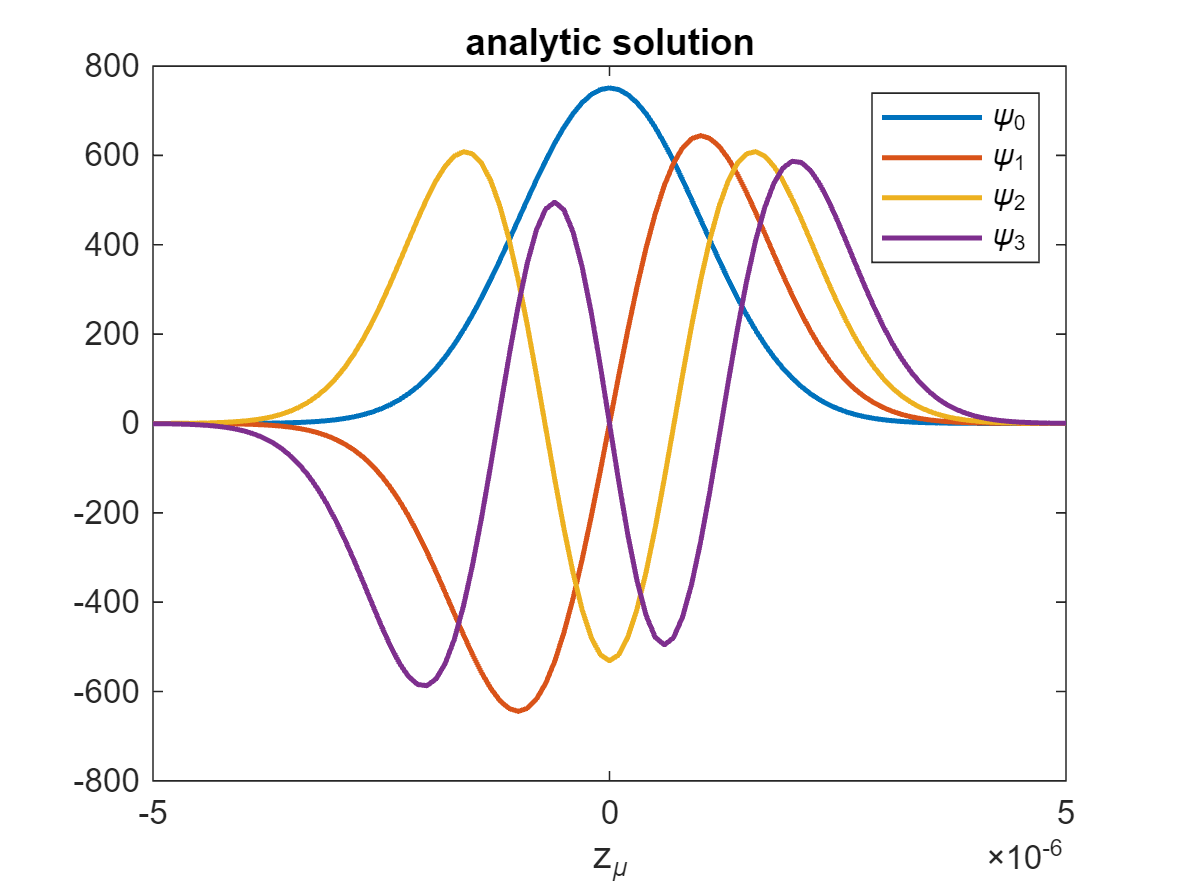

[PSI,Ej] = eigs(h,4,'smallestabs');
PSI0 = -PSI(:,1);
PSI1 = -PSI(:,2);
PSI2 = -PSI(:,3);
PSI3 = PSI(:,4);
% analytic solutions 
psi0 = (1/pi/z0^2)^(1/4)*exp(-z_mu.^2./2./z0^2);
psi1 = (1/sqrt(2))*psi0.*hermiteH(1,z_mu/z0);
psi2 = (1/sqrt(8))*psi0.*hermiteH(2,z_mu/z0);
psi3 = (1/sqrt(48))*psi0.*hermiteH(3,z_mu/z0);

% plot analytic
figure(1);
plot(z_mu,psi0,'LineWidth',1.5);
hold on;
plot(z_mu,psi1,'LineWidth',1.5);
plot(z_mu,psi2,'LineWidth',1.5);
plot(z_mu,psi3,'LineWidth',1.5);
hold off;
xlabel('z_\mu');
title('analytic solution');
legend('\psi_0','\psi_1','\psi_2','\psi_3');

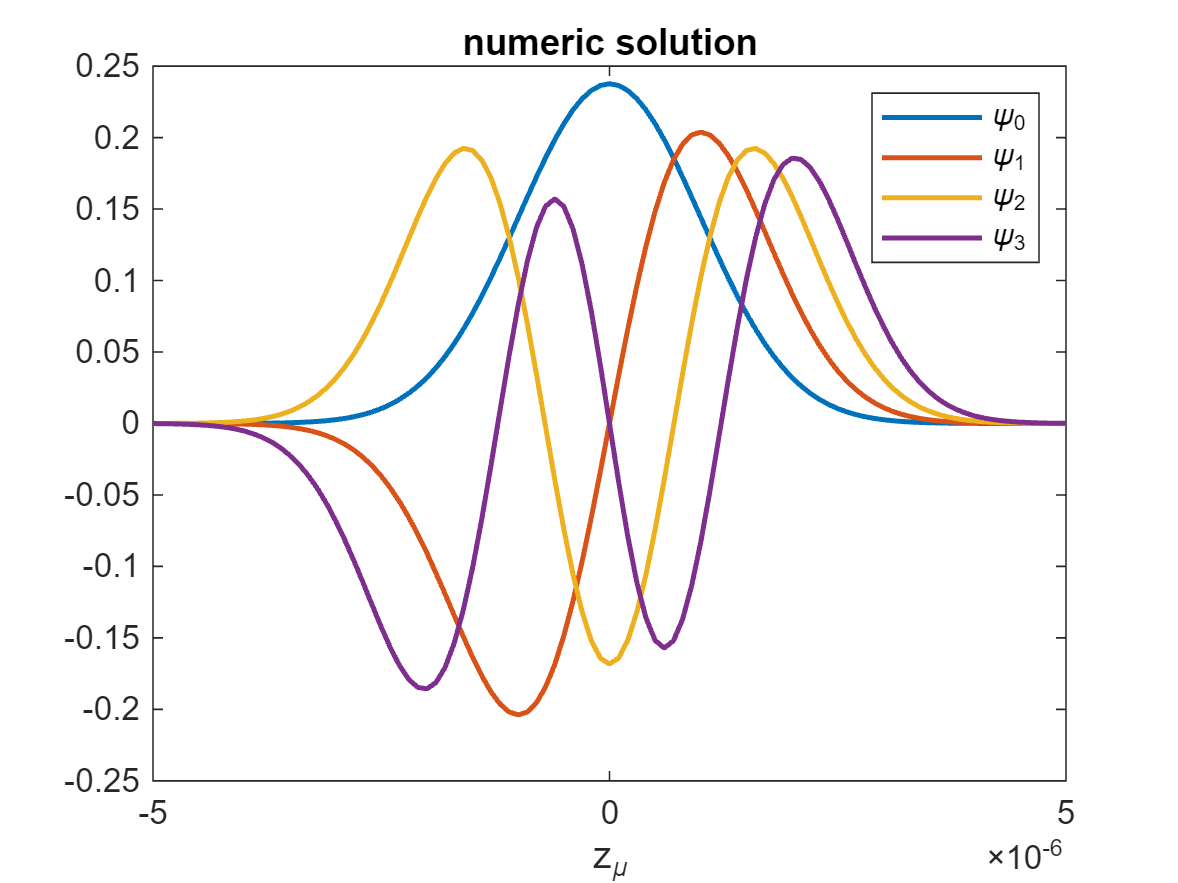


% plot numeric
figure(2);
plot(z_mu,PSI0,'LineWidth',1.5);
hold on;
plot(z_mu,PSI1,'LineWidth',1.5);
plot(z_mu,PSI2,'LineWidth',1.5);
plot(z_mu,PSI3,'LineWidth',1.5);
hold off;
xlabel('z_\mu');
title('numeric solution');
legend('\psi_0','\psi_1','\psi_2','\psi_3');

One crucial result coming from plotting the numeric solutions is that the fact that eigenvectors can be defined somewhat arbitrarily means that there might be extra negative signs attached to all of the components. this was the case for the first 3 eigenfunctions so they have been adjusted accordingly.